# Sparity of Dynamical Regression Vector

## Test generated matlab function

addpath("utils\");
Y_Full(zeros(1,7*3));

## Generate Random Kinematics

Random seed

rng(42);

Dataset size

dataset_size=5e4;

Kinematics dataset

KinematicsData=rand(dataset_size,7*3);
KinematicsData(:,1:7)=2*pi*KinematicsData(:,1:7);
KinematicsData(:,8:14)=2*pi*(KinematicsData(:,8:14)-0.5);
KinematicsData(:,15:21)=2*5*(KinematicsData(:,15:21)-0.5);

## Eliminate $0$-valued columns in $Y_{\text{Full}}$

Generate $Y_{\text{Full}}$ Dataset

DynFullMatData=zeros(dataset_size*7,7*10);
for i=1:dataset_size
    DynFullMatData(7*(i-1)+1:7*i,:)=Y_Full(KinematicsData(i,:));
end
ColumnNorm=zeros(1,7*10);
for i=1:7*10
    ColumnNorm(i)=norm(DynFullMatData(:,i));
end
NotZeroColIndice=ColumnNorm>1e-4;
DynRegMatData=DynFullMatData(:,NotZeroColIndice);
[~,DynRegMatColNum]=size(DynRegMatData);

## Generate Dynamical Regression Vector Dataset

DynRegVecData=zeros(dataset_size,7*DynRegMatColNum);
for i=1:dataset_size
    DynRegVecData(i,:)=reshape(DynRegMatData(7*(i-1)+1:7*i,:),...
        [1,7*DynRegMatColNum]);
end

## Sparity Analysis

Normalize Data

DynRegData_Normalized=zeros(dataset_size,7*DynRegMatColNum);
for i=1:7*DynRegMatColNum
    if DynRegVecData(:,i)==zeros(dataset_size,1)
        DynRegData_Normalized(:,i)=zeros(dataset_size,1);
    else
        DynRegData_Normalized(:,i)=normalize(DynRegVecData(:,i));
    end
end

Obtain Singular Value

s=svd(DynRegData_Normalized);
CompressedRank=sum(s>1e-5)

CompressedRank = 221

Visualization

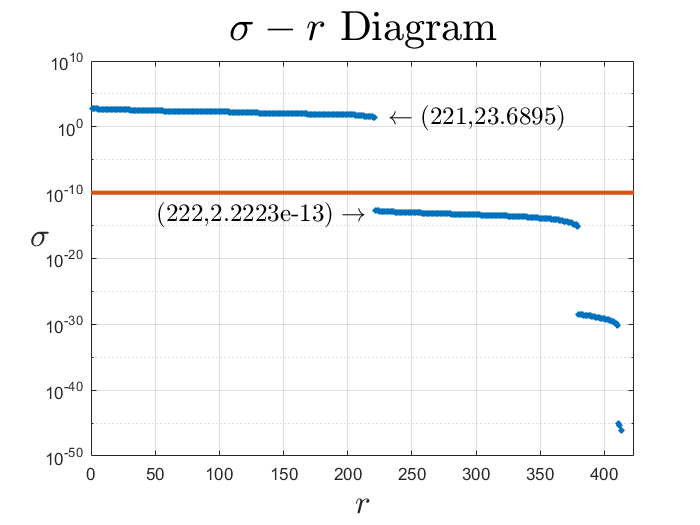

semilogy(s(1:7*DynRegMatColNum),"x","MarkerFaceColor",...
    "blue","MarkerSize",2.5,"LineWidth",3);
hold on
plot([0,length(s)+100],1e-10*[1,1],"LineWidth",2.5);
text(CompressedRank+10,s(CompressedRank),...
    "$\leftarrow($"+num2str(CompressedRank)+","+...
    num2str(s(CompressedRank))+"$)$","FontSize",...
    15,"Interpreter","latex")
text(CompressedRank-170,s(CompressedRank+1)/5,...
    "$($"+num2str(CompressedRank+1)+","+...
    num2str(s(CompressedRank+1))+"$)\rightarrow$","FontSize",...
    15,"Interpreter","latex")
hold off
grid on
xlabel("$r$","FontSize",20,"Interpreter","latex")
ylabel("$\sigma$","Rotation",0,"FontSize",20,"Interpreter","latex")
title("$\sigma-r$ Diagram","FontSize",25,"Interpreter","latex")
xlim([0,length(s)+10])

## Save Data

% KinematicsTable=array2table(KinematicsData,"VariableNames", ...
%     ["theta_1","theta_2","theta_3","theta_4","theta_5","theta_6",...
%     "theta_7","dtheta_1","dtheta_2","dtheta_3","dtheta_4",...
%     "dtheta_5","dtheta_6","dtheta_7","ddtheta_1","ddtheta_2",...
%     "ddtheta_3","ddtheta_4","ddtheta_5","ddtheta_6","ddtheta_7"]);
% writetable(KinematicsTable,"Data\KinematicsData.csv")
% writematrix(DynRegVecData,"Data\DynRegVecData.csv")
writematrix(NotZeroColIndice,"Data\DynParamterUsed.csv")
save("Data\KinematicsData.mat","KinematicsData")
save("Data\DynRegVecData.mat","DynRegVecData")

Remove path

rmpath("utils\")